# First Order Plus Dead Time (FOPDT) Models

**This lecture is broken into three portions:**

**(i) An Introduction to FOPDT Models**

**(ii) Time Delay in Dynamic Systems**

**(iii) Graphical Method to fit FOPDT Systems**

*In addition, please note that this lecture is best viewed with the code hidden using the button on the right toolbar:*

 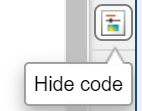

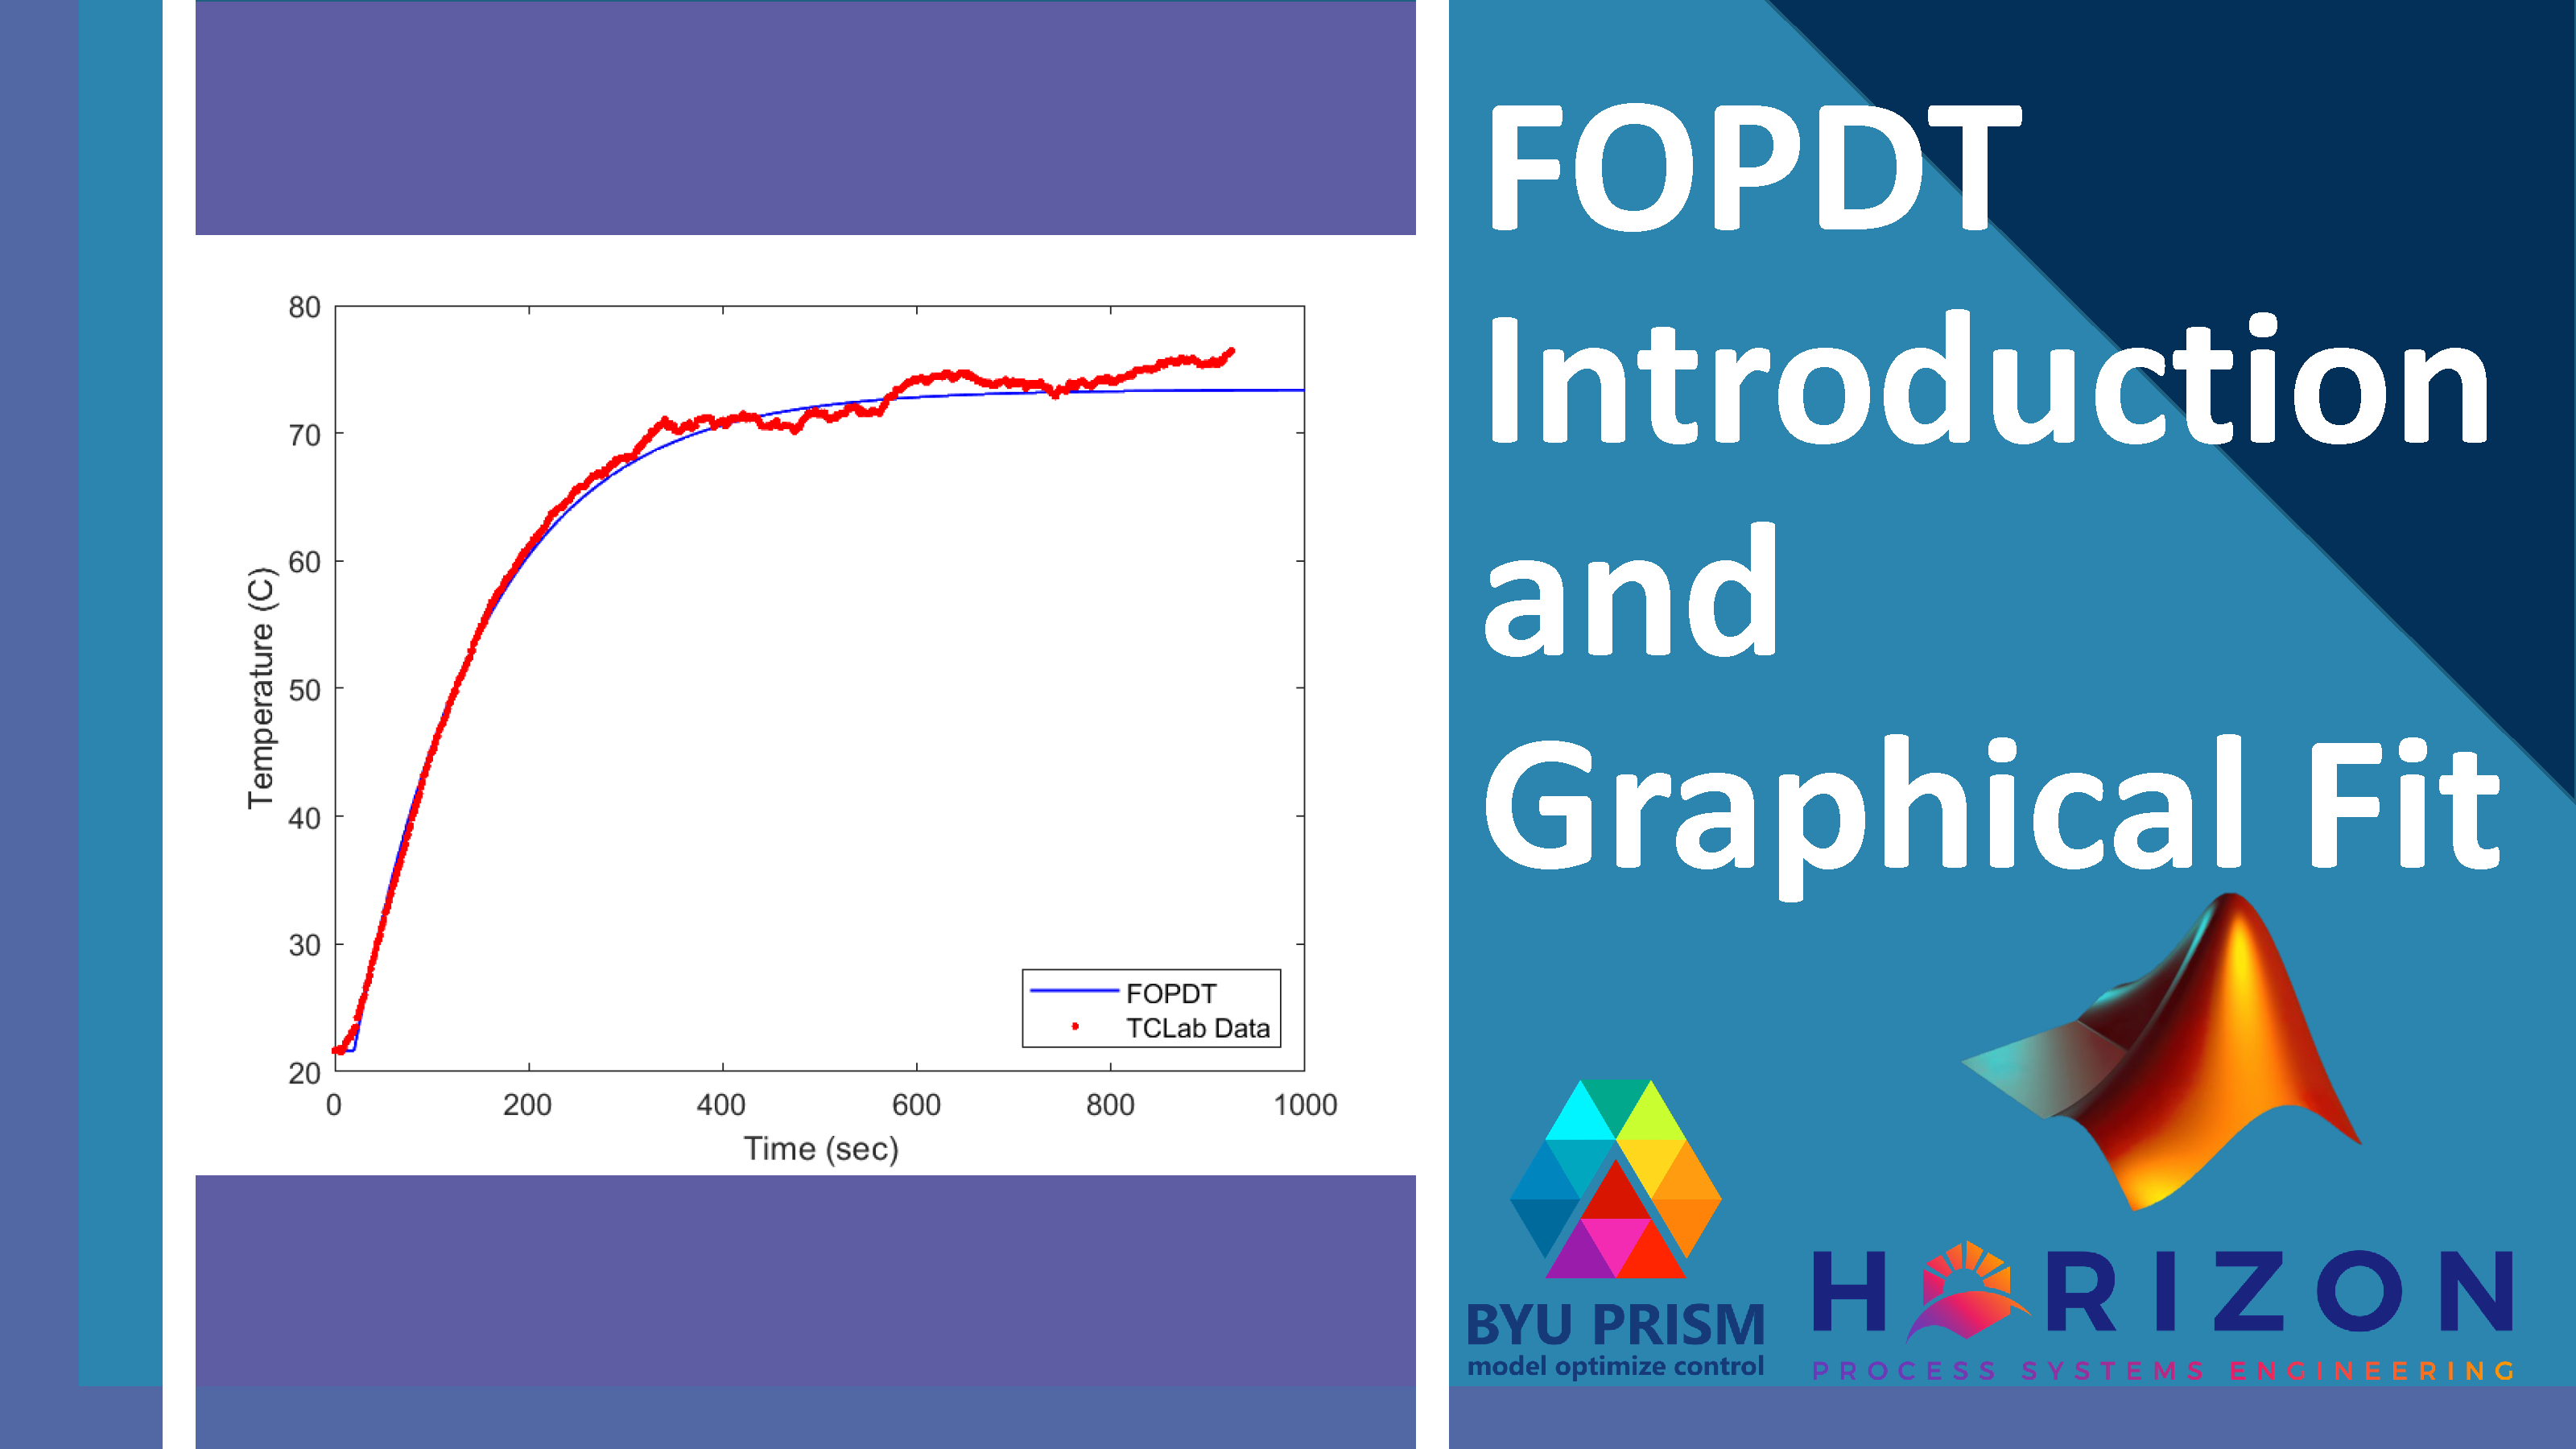

### [View Lecture](https://youtu.be/so-YzT-QsSQ)

# An Introduction to First Order Plus Dead Time Models

A first-order linear system with time delay is a common empirical description of many stable dynamic processes. The First Order Plus Dead Time (FOPDT) model is used to obtain initial controller tuning constants. The widget below demonstrates the effect of the three adjustable parameters in the FOPDT equation: the gain $K_p$, time constant $\tau_p$, and dead time $ \theta_p$. Sample data from the TCLab is shown as well to show how FOPDT models represent measured data.

clc; clear all; close all;

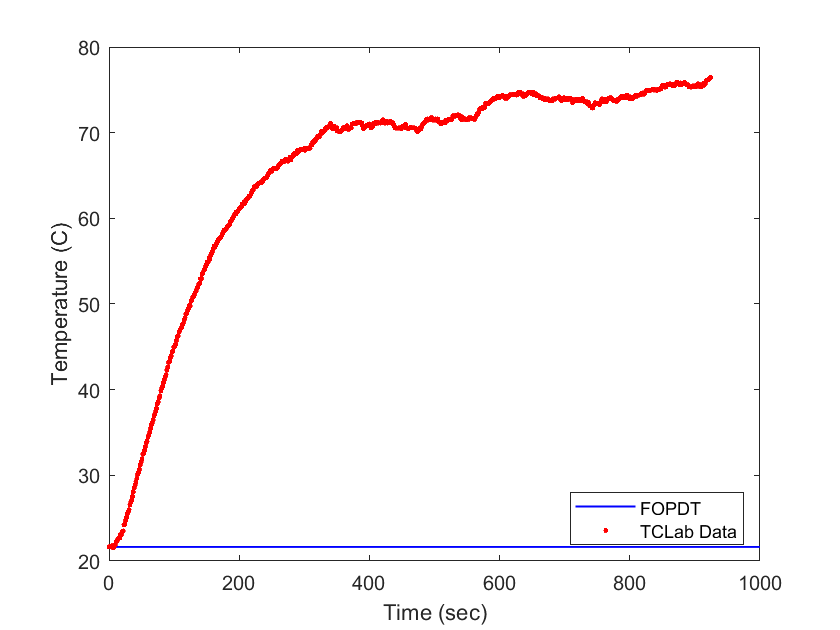

clf
figure(1)
K = 0;
Tau = 5;
Theta =  0;

tclab_time = [3.244000000000000247e-04 1.681868099999999977e+00 3.048612199999999994e+00 4.380380599999999625e+00 5.680423199999999895e+00 7.028389899999999635e+00 8.359443999999999875e+00 9.641192399999999552e+00 1.097152580000000022e+01 1.229727869999999967e+01 1.363416289999999975e+01 1.496187499999999915e+01 1.627504640000000080e+01 1.760799659999999989e+01 1.895299160000000072e+01 2.029293919999999929e+01 2.162708900000000156e+01 2.292388289999999884e+01 2.422603200000000001e+01 2.555432940000000031e+01 2.685979749999999910e+01 2.817978790000000089e+01 2.950974190000000164e+01 3.084170230000000146e+01 3.218572999999999951e+01 3.351865690000000342e+01 3.484866590000000031e+01 3.618481909999999857e+01 3.752057620000000071e+01 3.881360349999999926e+01 4.014151650000000160e+01 4.142665949999999953e+01 4.272564469999999659e+01 4.405741960000000290e+01 4.535742350000000300e+01 4.668340800000000002e+01 4.801452450000000027e+01 4.932132920000000098e+01 5.065728800000000120e+01 5.194231609999999932e+01 5.324741900000000072e+01 5.458024629999999888e+01 5.590620330000000138e+01 5.724107479999999981e+01 5.857213349999999963e+01 5.988727829999999841e+01 6.121641670000000346e+01 6.253908220000000284e+01 6.384620979999999690e+01 6.518637510000000646e+01 6.648912980000000061e+01 6.780955930000000365e+01 6.914268830000000321e+01 7.043089290000000346e+01 7.175501760000000218e+01 7.304701389999999606e+01 7.438179100000000687e+01 7.570977469999999698e+01 7.700274339999999995e+01 7.832476269999999374e+01 7.966209279999999637e+01 8.099382249999999317e+01 8.231161720000000059e+01 8.364160939999999300e+01 8.497259560000000533e+01 8.630256959999999822e+01 8.761570519999999362e+01 8.893049750000000131e+01 9.026363200000000120e+01 9.159362550000000169e+01 9.292260360000000219e+01 9.426000620000000652e+01 9.558811249999999404e+01 9.691707460000000651e+01 9.825814640000000111e+01 9.954447020000000634e+01 1.008822588999999965e+02 1.022112402000000060e+02 1.035408984000000032e+02 1.048751440000000059e+02 1.062078644000000054e+02 1.075437172999999973e+02 1.088790845000000047e+02 1.102132471999999979e+02 1.115220570999999978e+02 1.128557317000000069e+02 1.141686775999999952e+02 1.154839589999999987e+02 1.168151081999999974e+02 1.181478910000000013e+02 1.194352212999999949e+02 1.207748279000000053e+02 1.220441057000000029e+02 1.233729165999999964e+02 1.246617375000000010e+02 1.259691277000000014e+02 1.273067135000000007e+02 1.286056973000000028e+02 1.299336351000000036e+02 1.312206409000000065e+02 1.325260093999999924e+02 1.338627218999999968e+02 1.351521864000000051e+02 1.364804876000000036e+02 1.378126411000000076e+02 1.391516819999999939e+02 1.404703981000000113e+02 1.418025845999999888e+02 1.431143648999999982e+02 1.444488076000000092e+02 1.457809336999999914e+02 1.470792961999999875e+02 1.484043786999999952e+02 1.496883799000000010e+02 1.510077292000000000e+02 1.523346520999999996e+02 1.536425365000000056e+02 1.549450782000000117e+02 1.562238852000000122e+02 1.575399994999999933e+02 1.588647333000000117e+02 1.601399764999999888e+02 1.614123376999999948e+02 1.627108134000000064e+02 1.640499313999999913e+02 1.653876151000000050e+02 1.667217995000000030e+02 1.680568302000000074e+02 1.693708172000000047e+02 1.706943425000000047e+02 1.720265933999999959e+02 1.733659226000000046e+02 1.746666824000000133e+02 1.759925844999999924e+02 1.773137174000000016e+02 1.786442845999999918e+02 1.799631204000000082e+02 1.812655587000000139e+02 1.825911477999999875e+02 1.839011906000000067e+02 1.852014499000000001e+02 1.865173052000000098e+02 1.877805810000000122e+02 1.891006869999999935e+02 1.904183161999999925e+02 1.917383459000000130e+02 1.930663906999999995e+02 1.943722759000000053e+02 1.956268411000000071e+02 1.969554933000000005e+02 1.982793883999999878e+02 1.995871376999999995e+02 2.008723372000000040e+02 2.021807994000000122e+02 2.035086148999999978e+02 2.048121194999999943e+02 2.061402057999999897e+02 2.074599067999999988e+02 2.087488754999999969e+02 2.100069517999999960e+02 2.112685427000000118e+02 2.125701227000000131e+02 2.138368648999999948e+02 2.151328751000000068e+02 2.164567878000000007e+02 2.177177435000000116e+02 2.190357783000000040e+02 2.203347326999999893e+02 2.216489331999999877e+02 2.229277475000000095e+02 2.242470137999999906e+02 2.255699496000000011e+02 2.268774895999999899e+02 2.281765461999999900e+02 2.294560620999999969e+02 2.307796456000000092e+02 2.321084906000000103e+02 2.334005656999999871e+02 2.346755628999999885e+02 2.359699125999999865e+02 2.372918900999999892e+02 2.386195353999999895e+02 2.398936730000000068e+02 2.412306456000000026e+02 2.425112262000000101e+02 2.437919755000000066e+02 2.451177145999999993e+02 2.464144501000000105e+02 2.477336898000000076e+02 2.490011810999999966e+02 2.503354554999999948e+02 2.516635531999999955e+02 2.529580067999999926e+02 2.542778936999999928e+02 2.555345888999999886e+02 2.568150193999999829e+02 2.581389285999999856e+02 2.594732136999999739e+02 2.608099857999999927e+02 2.621428152999999952e+02 2.634835375999999769e+02 2.648134177000000022e+02 2.661165790000000015e+02 2.674577227999999991e+02 2.687821794000000182e+02 2.701205979000000070e+02 2.714003043999999818e+02 2.727231921000000057e+02 2.740529892999999788e+02 2.752955655999999749e+02 2.765571090999999910e+02 2.778625157000000172e+02 2.791885742000000050e+02 2.805060207999999875e+02 2.817861707000000138e+02 2.830630864999999972e+02 2.843889922999999840e+02 2.856798056000000088e+02 2.869855390999999827e+02 2.882792736000000104e+02 2.895992049000000179e+02 2.909233510999999908e+02 2.922466799000000037e+02 2.935661291999999776e+02 2.948899546000000100e+02 2.961940182999999820e+02 2.975253139999999803e+02 2.987670962999999915e+02 3.000122501000000170e+02 3.012880185000000210e+02 3.026026312999999845e+02 3.039075224000000048e+02 3.052046414999999797e+02 3.064039439000000016e+02 3.075703763999999865e+02 3.088498346000000083e+02 3.101740719000000013e+02 3.115061018999999760e+02 3.128006108000000154e+02 3.141251419999999825e+02 3.154490842999999813e+02 3.167469085999999834e+02 3.180738101000000029e+02 3.193307919000000084e+02 3.206046620999999845e+02 3.219405859999999961e+02 3.232440785000000005e+02 3.245288461999999754e+02 3.258364728000000241e+02 3.271579327000000035e+02 3.284866713000000118e+02 3.298174844999999777e+02 3.310931840999999736e+02 3.324191591000000017e+02 3.337283583999999905e+02 3.350536488999999847e+02 3.363933594000000085e+02 3.377163069000000064e+02 3.390472341000000256e+02 3.403872018000000139e+02 3.417121922000000040e+02 3.430481518999999935e+02 3.443811139000000026e+02 3.456634220000000255e+02 3.470005608999999822e+02 3.483392016999999896e+02 3.496287315000000149e+02 3.509636229000000185e+02 3.522896663999999873e+02 3.536139319999999771e+02 3.549424205999999913e+02 3.562603859999999827e+02 3.575968267999999739e+02 3.589318020000000047e+02 3.602627856999999949e+02 3.615953226999999970e+02 3.628844910999999911e+02 3.641867169000000217e+02 3.655159656999999811e+02 3.668406319000000053e+02 3.681555940999999734e+02 3.694887595000000147e+02 3.708167468999999983e+02 3.721485405000000242e+02 3.734793055000000095e+02 3.748165946999999960e+02 3.761464814000000274e+02 3.774734627999999930e+02 3.787843839000000230e+02 3.801140128999999774e+02 3.814097643999999718e+02 3.826943547000000194e+02 3.840342772999999852e+02 3.853572642999999971e+02 3.866863983000000076e+02 3.880261959000000047e+02 3.893437003000000232e+02 3.906770573000000013e+02 3.920042928999999958e+02 3.933260801000000129e+02 3.946552189000000226e+02 3.959510592999999972e+02 3.972700295999999867e+02 3.985983279999999809e+02 3.999318938000000117e+02 4.012616355999999769e+02 4.025961972999999716e+02 4.039208105999999816e+02 4.052401619999999980e+02 4.065760083999999779e+02 4.078977684999999838e+02 4.092327237999999738e+02 4.105529799999999909e+02 4.118692442000000256e+02 4.131991972999999803e+02 4.144975569000000064e+02 4.158310104000000251e+02 4.171477272000000198e+02 4.184796627000000058e+02 4.198019610000000057e+02 4.211292629000000147e+02 4.224632780000000025e+02 4.238002640000000270e+02 4.251035095999999953e+02 4.264234035999999719e+02 4.277596978999999919e+02 4.290933312999999885e+02 4.304278547999999773e+02 4.317527807000000166e+02 4.330314187000000175e+02 4.343612931000000117e+02 4.357001430999999911e+02 4.370361538999999880e+02 4.383719758999999954e+02 4.397020246000000157e+02 4.410389066999999841e+02 4.423607332000000270e+02 4.436762079000000085e+02 4.449659780000000069e+02 4.463068240000000060e+02 4.476340164999999729e+02 4.489209167999999863e+02 4.502638132999999812e+02 4.515877100999999811e+02 4.529228135999999836e+02 4.542599882000000093e+02 4.555570549999999912e+02 4.568798572000000036e+02 4.582077057999999852e+02 4.595387210000000096e+02 4.608687992999999778e+02 4.622005293000000279e+02 4.635054092999999966e+02 4.648322059999999851e+02 4.661182825000000207e+02 4.674564096999999947e+02 4.687655020999999920e+02 4.700714985999999840e+02 4.713983440000000087e+02 4.727304240999999934e+02 4.740552157999999849e+02 4.753898504000000003e+02 4.767121460999999840e+02 4.780452622000000247e+02 4.793664046999999755e+02 4.806944154000000253e+02 4.820335916999999881e+02 4.833366480000000251e+02 4.846595682999999894e+02 4.859891496999999845e+02 4.872962448999999765e+02 4.886263549999999896e+02 4.899677500000000236e+02 4.912761978999999997e+02 4.925964200999999889e+02 4.939347602000000279e+02 4.952691343000000188e+02 4.966033398000000147e+02 4.979025629000000208e+02 4.992314266999999859e+02 5.005703080999999770e+02 5.018876439000000005e+02 5.032159487999999783e+02 5.045405981000000111e+02 5.058650663000000236e+02 5.071507139999999936e+02 5.084773402000000146e+02 5.097647028000000091e+02 5.110858471999999892e+02 5.124236035000000129e+02 5.137333889000000227e+02 5.150576552999999649e+02 5.163895477999999457e+02 5.177204950000000281e+02 5.190564359999999624e+02 5.203666005999999697e+02 5.216823650000000043e+02 5.230148860000000468e+02 5.243013307999999597e+02 5.256303772999999637e+02 5.269644156000000521e+02 5.282981809000000339e+02 5.296393205000000535e+02 5.309290448000000424e+02 5.322632104000000481e+02 5.335958716000000095e+02 5.349109826999999768e+02 5.362455519999999751e+02 5.375771006999999599e+02 5.388604066999999986e+02 5.401907265999999481e+02 5.414841760000000477e+02 5.428000017000000526e+02 5.441348328000000265e+02 5.454675482999999758e+02 5.468088612000000239e+02 5.481454036000000087e+02 5.494235813000000235e+02 5.507527688999999782e+02 5.520903664999999592e+02 5.534154129999999441e+02 5.547476648000000523e+02 5.560766128999999864e+02 5.574036561000000347e+02 5.587386813000000529e+02 5.600425838999999542e+02 5.613319469000000481e+02 5.626586240999999973e+02 5.639673881999999594e+02 5.652954829999999902e+02 5.666034601000000066e+02 5.679263852999999926e+02 5.692597075999999561e+02 5.705972686000000067e+02 5.719280248999999685e+02 5.732624724999999444e+02 5.745894978000000037e+02 5.759169871000000285e+02 5.772442346999999927e+02 5.785732113999999910e+02 5.799061877999999979e+02 5.812510031000000481e+02 5.825788231000000224e+02 5.839100985999999693e+02 5.852471020000000408e+02 5.865618838000000324e+02 5.878941647999999986e+02 5.892321348000000398e+02 5.905609153999999990e+02 5.918951438999999937e+02 5.932342175999999654e+02 5.945520169999999780e+02 5.958888783999999532e+02 5.972297953999999436e+02 5.985439539999999852e+02 5.998747425999999905e+02 6.012157270000000153e+02 6.025107037000000219e+02 6.038436374999999998e+02 6.051642931999999746e+02 6.064795976999999993e+02 6.078095369000000119e+02 6.091342137999999977e+02 6.104470364000000018e+02 6.117940925000000334e+02 6.130784261000000015e+02 6.144104248999999527e+02 6.157464605999999776e+02 6.170482833999999457e+02 6.183793435000000045e+02 6.197101523999999699e+02 6.210412741999999753e+02 6.223703977000000123e+02 6.236942027000000053e+02 6.250051293999999871e+02 6.263333899000000429e+02 6.276344994999999471e+02 6.289607095999999729e+02 6.302958260000000337e+02 6.316200959999999895e+02 6.329540865999999824e+02 6.342865604999999505e+02 6.356249951999999439e+02 6.369509398000000147e+02 6.382559344000000010e+02 6.395867369999999710e+02 6.409107228000000305e+02 6.422135024000000385e+02 6.435427724999999555e+02 6.448806803999999602e+02 6.461639152000000195e+02 6.474908666999999696e+02 6.488203843000000006e+02 6.501356912999999622e+02 6.514706509000000096e+02 6.528047023999999965e+02 6.541360284999999521e+02 6.554695625000000518e+02 6.567528743999999961e+02 6.580835750999999618e+02 6.593853894999999739e+02 6.606787164999999504e+02 6.620134153999999853e+02 6.633132467000000361e+02 6.646452282000000196e+02 6.659735435999999709e+02 6.672918478999999934e+02 6.686203099000000520e+02 6.699166778000000022e+02 6.712492442999999867e+02 6.725780767999999625e+02 6.739065444999999954e+02 6.751881720000000087e+02 6.765140034999999443e+02 6.778417160999999851e+02 6.791741114999999809e+02 6.805090622999999823e+02 6.818003416999999899e+02 6.831417060999999649e+02 6.844439879000000246e+02 6.857798097999999527e+02 6.871079565999999659e+02 6.884366317000000208e+02 6.897594953000000260e+02 6.910890064999999822e+02 6.924069455999999718e+02 6.937358089000000518e+02 6.950697870000000194e+02 6.964025425999999470e+02 6.977309046000000308e+02 6.990662721999999576e+02 7.003536317000000508e+02 7.016842083999999886e+02 7.029695897000000286e+02 7.042556178999999474e+02 7.056006525999999894e+02 7.069285155999999688e+02 7.082455125000000180e+02 7.095754826999999523e+02 7.108984424000000217e+02 7.122344659000000320e+02 7.135515894999999773e+02 7.148844394000000193e+02 7.162130912000000080e+02 7.175397647999999435e+02 7.188692832000000408e+02 7.202044177000000218e+02 7.215303692999999612e+02 7.228314378999999690e+02 7.241582220000000234e+02 7.254845523999999841e+02 7.268259255000000394e+02 7.281535949000000301e+02 7.294854593999999679e+02 7.308022144999999909e+02 7.321319458000000395e+02 7.334630714999999554e+02 7.347939520999999559e+02 7.360911764999999605e+02 7.374172297000000071e+02 7.387426285000000235e+02 7.400478090000000293e+02 7.413747104999999920e+02 7.426965807000000268e+02 7.439766548000000057e+02 7.453058035000000245e+02 7.466338233999999829e+02 7.479577153000000180e+02 7.492796064000000342e+02 7.506126136000000315e+02 7.519376812000000427e+02 7.532655561000000262e+02 7.546084968999999774e+02 7.558917152000000215e+02 7.572156208000000106e+02 7.584986017999999603e+02 7.598354798000000301e+02 7.611487964000000375e+02 7.624497396000000435e+02 7.637833302999999887e+02 7.651107459999999492e+02 7.664377610999999888e+02 7.677710237999999663e+02 7.690952104000000418e+02 7.704096988000000010e+02 7.717383370000000014e+02 7.730537411999999904e+02 7.743839070000000220e+02 7.757170591000000286e+02 7.770500107999999955e+02 7.783745460000000094e+02 7.797056214000000409e+02 7.810381339000000480e+02 7.823759122000000161e+02 7.836676092000000153e+02 7.850006087000000434e+02 7.863298718999999437e+02 7.876406482999999525e+02 7.889698154000000159e+02 7.903002887999999757e+02 7.916276116000000229e+02 7.929571547000000464e+02 7.942688634999999522e+02 7.955347623999999769e+02 7.968723016000000143e+02 7.982148200000000315e+02 7.995290052000000287e+02 8.008543647000000192e+02 8.021740135000000009e+02 8.034964758999999503e+02 8.048198859000000311e+02 8.061196198000000095e+02 8.074474146999999675e+02 8.087440444000000070e+02 8.100665318000000070e+02 8.114000267999999778e+02 8.127312829999999622e+02 8.140642765999999710e+02 8.153982525000000123e+02 8.166841888000000154e+02 8.180183557999999948e+02 8.193312147000000323e+02 8.206658119999999599e+02 8.220001140000000532e+02 8.233098969999999781e+02 8.246360888000000386e+02 8.259638736000000563e+02 8.272839305999999624e+02 8.286139627000000019e+02 8.299479624000000513e+02 8.312819124000000102e+02 8.326107170999999880e+02 8.339426803000000064e+02 8.352657443000000512e+02 8.365941939000000502e+02 8.378803619999999910e+02 8.392015102000000297e+02 8.405340248999999631e+02 8.418589563000000453e+02 8.431893324999999777e+02 8.444878232999999454e+02 8.457716481999999587e+02 8.471006059999999707e+02 8.484196349000000055e+02 8.497606762000000344e+02 8.510899657999999590e+02 8.524264500000000453e+02 8.537566938999999593e+02 8.550854219000000285e+02 8.563994060999999647e+02 8.577373675999999705e+02 8.590753218999999490e+02 8.603941495999999916e+02 8.617208974000000126e+02 8.630192395999999917e+02 8.643348779000000377e+02 8.656616767000000436e+02 8.669481584000000112e+02 8.682661619000000428e+02 8.695972991999999522e+02 8.709319518999999445e+02 8.722670801000000438e+02 8.736009841999999708e+02 8.749270238000000290e+02 8.762559906999999839e+02 8.775779009999999971e+02 8.789035538000000543e+02 8.802348790999999437e+02 8.815605815999999777e+02 8.828648050000000467e+02 8.841948204000000260e+02 8.855107911000000058e+02 8.868236991999999645e+02 8.881537114000000201e+02 8.894767897000000403e+02 8.908109838000000309e+02 8.921396796000000222e+02 8.934746023000000150e+02 8.948059712000000445e+02 8.961234183999999914e+02 8.974566992000000027e+02 8.987883925999999519e+02 9.001195596000000023e+02 9.014555951999999479e+02 9.027874435999999605e+02 9.041003793999999516e+02 9.053943435999999565e+02 9.067212104000000181e+02 9.080553208999999697e+02 9.093872877999999673e+02 9.107154256999999689e+02 9.120570900999999822e+02 9.133583426000000145e+02 9.146863219000000527e+02 9.159861239000000523e+02 9.173152697000000444e+02 9.186309654000000364e+02 9.199462333999999828e+02 9.212830099000000246e+02 9.226179968999999801e+02 9.239038020000000415e+02];
tclab_temp = [2.165200391006840164e+01 2.165200391006840164e+01 2.174975562072339841e+01 2.160312805474099918e+01 2.179863147605080087e+01 2.155425219941350079e+01 2.174975562072339841e+01 2.189638318670580119e+01 2.228739002932550051e+01 2.228739002932550051e+01 2.258064516129029897e+01 2.267839687194529930e+01 2.267839687194529930e+01 2.306940371456499861e+01 2.306940371456499861e+01 2.341153470185729901e+01 2.350928641251219986e+01 2.424242424242429905e+01 2.434017595307919990e+01 2.473118279569889921e+01 2.507331378299119962e+01 2.546432062561099841e+01 2.570869990224829849e+01 2.600195503421310050e+01 2.653958944281529853e+01 2.688172043010749945e+01 2.712609970674489901e+01 2.756598240469210026e+01 2.805474095796679990e+01 2.854349951124149953e+01 2.883675464320630155e+01 2.927663734115349925e+01 2.961876832844579965e+01 3.010752688172039981e+01 3.030303030303030098e+01 3.069403714565009977e+01 3.118279569892469993e+01 3.157380254154449872e+01 3.191593352883669965e+01 3.245356793743889767e+01 3.260019550342129691e+01 3.294232649071359731e+01 3.333333333333330017e+01 3.382209188660799981e+01 3.396871945259039904e+01 3.445747800586509868e+01 3.475073313782989715e+01 3.499511241446730025e+01 3.543499511241449795e+01 3.587487781036170276e+01 3.616813294232650122e+01 3.646138807429129969e+01 3.695014662756599932e+01 3.719452590420330296e+01 3.743890518084069896e+01 3.782991202346040183e+01 3.831867057673510146e+01 3.856304985337239799e+01 3.900293255131970227e+01 3.929618768328450074e+01 3.988269794721409767e+01 4.017595307917890324e+01 4.042033235581619977e+01 4.081133919843600211e+01 4.115347018572830251e+01 4.149560117302050344e+01 4.173998044965789944e+01 4.227761485826000154e+01 4.266862170087979678e+01 4.320625610948189887e+01 4.330400782013690275e+01 4.369501466275659851e+01 4.393939393939390214e+01 4.437927663734119932e+01 4.447702834799609661e+01 4.496578690127080336e+01 4.501466275659819871e+01 4.525904203323560182e+01 4.574780058651030146e+01 4.618768328445749916e+01 4.623655913978490162e+01 4.667644183773219879e+01 4.692082111436950242e+01 4.711632453567939649e+01 4.726295210166180283e+01 4.765395894428149859e+01 4.775171065493640299e+01 4.814271749755619823e+01 4.838709677419360133e+01 4.882697947214079903e+01 4.897360703812319827e+01 4.921798631476050190e+01 4.951124144672530036e+01 4.985337243401760077e+01 4.980449657869009883e+01 5.029325513196479847e+01 5.048875855327469964e+01 5.083088954056700004e+01 5.092864125122189733e+01 5.107526881720429657e+01 5.136852394916910214e+01 5.151515151515150137e+01 5.180840664711629984e+01 5.200391006842620101e+01 5.234604105571850141e+01 5.244379276637339871e+01 5.293255131964809834e+01 5.298142717497560028e+01 5.347018572825020044e+01 5.361681329423259967e+01 5.391006842619739814e+01 5.405669599217979737e+01 5.439882697947209778e+01 5.459433040078199895e+01 5.488758553274679741e+01 5.493646138807429935e+01 5.537634408602149705e+01 5.522971652003909782e+01 5.566959921798630262e+01 5.591397849462359915e+01 5.606060606060599838e+01 5.640273704789829878e+01 5.674486803519059919e+01 5.669599217986309725e+01 5.689149560117299842e+01 5.703812316715539765e+01 5.728250244379280076e+01 5.752688172043009729e+01 5.762463343108500169e+01 5.772238514173999846e+01 5.786901270772239769e+01 5.801564027370479693e+01 5.826001955034210056e+01 5.845552297165200173e+01 5.865102639296190290e+01 5.869990224828939773e+01 5.879765395894430213e+01 5.894428152492670137e+01 5.904203323558159866e+01 5.913978494623660254e+01 5.933528836754639713e+01 5.957966764418380023e+01 5.972629521016609999e+01 5.992179863147600116e+01 6.001955034213099793e+01 6.031280547409580350e+01 6.045943304007820274e+01 6.050830889540569757e+01 6.075268817204300120e+01 6.075268817204300120e+01 6.089931573802540044e+01 6.104594330400779967e+01 6.119257086999019890e+01 6.133919843597259813e+01 6.138807429130010007e+01 6.168132942326489854e+01 6.163245356793739660e+01 6.192570869990220217e+01 6.173020527859240048e+01 6.197458455522969700e+01 6.221896383186700064e+01 6.226783968719450257e+01 6.241446725317690181e+01 6.260997067448680298e+01 6.260997067448680298e+01 6.275659824046920221e+01 6.300097751710649874e+01 6.329423264907129720e+01 6.334310850439879914e+01 6.368523949169109954e+01 6.368523949169109954e+01 6.373411534701860148e+01 6.373411534701860148e+01 6.397849462365589801e+01 6.407624633431089478e+01 6.412512218963830435e+01 6.417399804496579918e+01 6.427174975562070358e+01 6.417399804496579918e+01 6.432062561094819841e+01 6.456500488758550205e+01 6.461388074291299688e+01 6.471163245356790128e+01 6.476050830889539611e+01 6.485826001955030051e+01 6.500488758553269975e+01 6.524926686217010285e+01 6.529814271749749821e+01 6.559139784946239615e+01 6.564027370478980572e+01 6.549364613880740649e+01 6.568914956011730055e+01 6.583577712609969979e+01 6.583577712609969979e+01 6.578690127077220495e+01 6.578690127077220495e+01 6.588465298142719462e+01 6.603128054740959385e+01 6.617790811339199308e+01 6.627565982404689748e+01 6.642228739002939619e+01 6.652003910068420112e+01 6.666666666666669983e+01 6.661779081133920499e+01 6.671554252199409518e+01 6.666666666666669983e+01 6.686217008797649441e+01 6.681329423264909906e+01 6.681329423264909906e+01 6.666666666666669983e+01 6.681329423264909906e+01 6.710654936461389752e+01 6.681329423264909906e+01 6.715542521994130709e+01 6.725317693059629676e+01 6.744868035190620503e+01 6.739980449657869599e+01 6.759530791788860427e+01 6.754643206256109522e+01 6.764418377321599962e+01 6.793743890518079809e+01 6.779081133919849833e+01 6.788856304985340273e+01 6.803519061583580196e+01 6.798631476050829292e+01 6.808406647116329680e+01 6.803519061583580196e+01 6.808406647116329680e+01 6.818181818181820120e+01 6.793743890518079809e+01 6.813294232649070636e+01 6.808406647116329680e+01 6.818181818181820120e+01 6.813294232649070636e+01 6.818181818181820120e+01 6.818181818181820120e+01 6.852394916911049449e+01 6.857282502443790406e+01 6.886608015640270253e+01 6.886608015640270253e+01 6.911045943304010564e+01 6.901270772238520124e+01 6.925708699902250487e+01 6.940371456500490410e+01 6.955034213098730334e+01 6.950146627565979429e+01 6.959921798631479817e+01 6.979472140762460697e+01 7.013685239491690027e+01 6.999022482893450103e+01 7.003910068426199587e+01 7.018572825024439510e+01 7.023460410557190414e+01 7.043010752688169873e+01 7.062561094819160701e+01 7.052785923753670261e+01 7.062561094819160701e+01 7.067448680351910184e+01 7.086999022482889643e+01 7.111436950146629954e+01 7.082111436950150107e+01 7.047898338220919356e+01 7.077223851417400624e+01 7.072336265884649720e+01 7.052785923753670261e+01 7.047898338220919356e+01 7.057673509286409796e+01 7.018572825024439510e+01 7.018572825024439510e+01 7.013685239491690027e+01 7.008797653958950491e+01 7.023460410557190414e+01 7.033235581622679433e+01 7.038123167155430338e+01 7.057673509286409796e+01 7.062561094819160701e+01 7.043010752688169873e+01 7.057673509286409796e+01 7.082111436950150107e+01 7.052785923753670261e+01 7.038123167155430338e+01 7.057673509286409796e+01 7.057673509286409796e+01 7.057673509286409796e+01 7.101661779081139514e+01 7.101661779081139514e+01 7.111436950146629954e+01 7.101661779081139514e+01 7.111436950146629954e+01 7.116324535679379437e+01 7.111436950146629954e+01 7.121212121212120394e+01 7.121212121212120394e+01 7.121212121212120394e+01 7.116324535679379437e+01 7.111436950146629954e+01 7.086999022482889643e+01 7.047898338220919356e+01 7.057673509286409796e+01 7.062561094819160701e+01 7.077223851417400624e+01 7.082111436950150107e+01 7.091886608015640547e+01 7.096774193548390031e+01 7.101661779081129566e+01 7.072336265884649720e+01 7.057673509286409796e+01 7.062561094819160701e+01 7.077223851417400624e+01 7.106549364613880471e+01 7.101661779081139514e+01 7.121212121212120394e+01 7.111436950146629954e+01 7.121212121212120394e+01 7.111436950146629954e+01 7.116324535679379437e+01 7.116324535679379437e+01 7.111436950146629954e+01 7.121212121212120394e+01 7.140762463343109800e+01 7.150537634408600240e+01 7.140762463343109800e+01 7.111436950146629954e+01 7.121212121212120394e+01 7.130987292277619360e+01 7.111436950146629954e+01 7.121212121212120394e+01 7.126099706744869877e+01 7.130987292277619360e+01 7.126099706744869877e+01 7.111436950146629954e+01 7.116324535679379437e+01 7.091886608015640547e+01 7.077223851417400624e+01 7.057673509286409796e+01 7.052785923753670261e+01 7.052785923753670261e+01 7.052785923753670261e+01 7.057673509286409796e+01 7.052785923753670261e+01 7.052785923753670261e+01 7.047898338220919356e+01 7.062561094819160701e+01 7.072336265884659667e+01 7.077223851417400624e+01 7.091886608015640547e+01 7.096774193548390031e+01 7.052785923753670261e+01 7.052785923753670261e+01 7.047898338220919356e+01 7.052785923753670261e+01 7.057673509286409796e+01 7.062561094819160701e+01 7.057673509286409796e+01 7.057673509286409796e+01 7.057673509286409796e+01 7.057673509286409796e+01 7.052785923753670261e+01 7.038123167155430338e+01 7.023460410557190414e+01 7.013685239491690027e+01 7.023460410557190414e+01 7.033235581622679433e+01 7.052785923753670261e+01 7.047898338220919356e+01 7.082111436950150107e+01 7.101661779081139514e+01 7.111436950146629954e+01 7.121212121212120394e+01 7.126099706744869877e+01 7.150537634408600240e+01 7.160312805474100628e+01 7.145650048875860705e+01 7.150537634408600240e+01 7.160312805474100628e+01 7.165200391006840164e+01 7.174975562072340551e+01 7.160312805474100628e+01 7.145650048875860705e+01 7.155425219941349724e+01 7.145650048875860705e+01 7.160312805474100628e+01 7.155425219941349724e+01 7.160312805474100628e+01 7.130987292277619360e+01 7.126099706744869877e+01 7.121212121212120394e+01 7.101661779081139514e+01 7.111436950146629954e+01 7.111436950146629954e+01 7.126099706744869877e+01 7.121212121212120394e+01 7.116324535679379437e+01 7.145650048875860705e+01 7.140762463343109800e+01 7.145650048875860705e+01 7.155425219941349724e+01 7.150537634408600240e+01 7.160312805474100628e+01 7.150537634408600240e+01 7.160312805474100628e+01 7.199413489736069494e+01 7.199413489736069494e+01 7.189638318670580475e+01 7.194525904203320010e+01 7.204301075268820398e+01 7.194525904203329958e+01 7.209188660801569881e+01 7.189638318670580475e+01 7.199413489736069494e+01 7.160312805474100628e+01 7.150537634408600240e+01 7.184750733137829570e+01 7.155425219941349724e+01 7.160312805474100628e+01 7.160312805474100628e+01 7.155425219941349724e+01 7.150537634408600240e+01 7.155425219941349724e+01 7.155425219941349724e+01 7.174975562072330604e+01 7.170087976539589647e+01 7.174975562072340551e+01 7.170087976539589647e+01 7.160312805474100628e+01 7.170087976539589647e+01 7.155425219941349724e+01 7.174975562072330604e+01 7.194525904203320010e+01 7.214076246334309417e+01 7.214076246334309417e+01 7.238514173998049728e+01 7.267839687194529574e+01 7.282502443792769498e+01 7.277614858260020014e+01 7.277614858260020014e+01 7.297165200391009421e+01 7.287390029325520402e+01 7.297165200391009421e+01 7.341153470185730612e+01 7.336265884652979707e+01 7.346041055718480095e+01 7.341153470185730612e+01 7.346041055718480095e+01 7.360703812316710071e+01 7.365591397849459554e+01 7.375366568914959942e+01 7.390029325513199865e+01 7.390029325513199865e+01 7.404692082111439788e+01 7.394916911045949348e+01 7.409579667644179324e+01 7.409579667644179324e+01 7.424242424242420668e+01 7.404692082111439788e+01 7.419354838709679711e+01 7.424242424242430616e+01 7.429130009775170151e+01 7.424242424242430616e+01 7.434017595307919635e+01 7.429130009775170151e+01 7.424242424242430616e+01 7.399804496578690305e+01 7.399804496578690305e+01 7.424242424242420668e+01 7.419354838709679711e+01 7.424242424242430616e+01 7.438905180840660591e+01 7.443792766373410075e+01 7.443792766373410075e+01 7.443792766373410075e+01 7.443792766373410075e+01 7.448680351906159558e+01 7.448680351906159558e+01 7.448680351906159558e+01 7.438905180840660591e+01 7.458455522971649998e+01 7.468230694037140438e+01 7.468230694037150386e+01 7.468230694037150386e+01 7.448680351906159558e+01 7.448680351906159558e+01 7.453567937438910462e+01 7.424242424242430616e+01 7.429130009775170151e+01 7.429130009775170151e+01 7.443792766373410075e+01 7.448680351906159558e+01 7.458455522971649998e+01 7.468230694037150386e+01 7.463343108504399481e+01 7.468230694037150386e+01 7.463343108504399481e+01 7.453567937438910462e+01 7.473118279569889921e+01 7.443792766373410075e+01 7.443792766373410075e+01 7.453567937438900515e+01 7.434017595307919635e+01 7.438905180840660591e+01 7.429130009775170151e+01 7.429130009775170151e+01 7.409579667644179324e+01 7.414467253176930228e+01 7.409579667644179324e+01 7.394916911045949348e+01 7.404692082111439788e+01 7.404692082111439788e+01 7.385141739980450382e+01 7.390029325513199865e+01 7.394916911045949348e+01 7.394916911045939401e+01 7.385141739980450382e+01 7.380254154447699477e+01 7.370478983382210458e+01 7.370478983382210458e+01 7.375366568914959942e+01 7.394916911045939401e+01 7.390029325513199865e+01 7.390029325513199865e+01 7.394916911045949348e+01 7.404692082111439788e+01 7.404692082111439788e+01 7.404692082111439788e+01 7.419354838709679711e+01 7.399804496578690305e+01 7.404692082111439788e+01 7.375366568914959942e+01 7.390029325513199865e+01 7.394916911045949348e+01 7.409579667644179324e+01 7.399804496578690305e+01 7.385141739980450382e+01 7.385141739980450382e+01 7.385141739980450382e+01 7.399804496578690305e+01 7.390029325513199865e+01 7.404692082111439788e+01 7.394916911045949348e+01 7.380254154447699477e+01 7.350928641251219631e+01 7.365591397849459554e+01 7.385141739980450382e+01 7.375366568914959942e+01 7.375366568914959942e+01 7.390029325513199865e+01 7.375366568914959942e+01 7.390029325513199865e+01 7.370478983382210458e+01 7.390029325513199865e+01 7.370478983382210458e+01 7.399804496578690305e+01 7.390029325513199865e+01 7.365591397849459554e+01 7.360703812316720018e+01 7.360703812316720018e+01 7.360703812316720018e+01 7.341153470185730612e+01 7.355816226783970535e+01 7.331378299120230224e+01 7.311827956989249344e+01 7.311827956989249344e+01 7.306940371456499861e+01 7.287390029325520402e+01 7.311827956989249344e+01 7.321603128054739784e+01 7.350928641251219631e+01 7.341153470185730612e+01 7.336265884652979707e+01 7.341153470185730612e+01 7.346041055718480095e+01 7.326490713587490688e+01 7.350928641251219631e+01 7.370478983382210458e+01 7.394916911045949348e+01 7.380254154447699477e+01 7.360703812316720018e+01 7.390029325513199865e+01 7.375366568914959942e+01 7.360703812316720018e+01 7.380254154447699477e+01 7.390029325513199865e+01 7.399804496578690305e+01 7.394916911045949348e+01 7.409579667644190692e+01 7.394916911045949348e+01 7.390029325513199865e+01 7.375366568914959942e+01 7.380254154447699477e+01 7.370478983382210458e+01 7.370478983382210458e+01 7.365591397849469502e+01 7.385141739980450382e+01 7.385141739980450382e+01 7.394916911045949348e+01 7.409579667644179324e+01 7.409579667644179324e+01 7.424242424242420668e+01 7.404692082111439788e+01 7.414467253176930228e+01 7.424242424242420668e+01 7.409579667644179324e+01 7.419354838709679711e+01 7.438905180840660591e+01 7.409579667644179324e+01 7.419354838709679711e+01 7.419354838709679711e+01 7.394916911045949348e+01 7.414467253176930228e+01 7.394916911045949348e+01 7.404692082111439788e+01 7.409579667644179324e+01 7.419354838709679711e+01 7.438905180840660591e+01 7.424242424242430616e+01 7.438905180840660591e+01 7.438905180840660591e+01 7.438905180840660591e+01 7.443792766373410075e+01 7.453567937438910462e+01 7.448680351906159558e+01 7.463343108504399481e+01 7.458455522971649998e+01 7.448680351906159558e+01 7.463343108504399481e+01 7.482893450635390309e+01 7.497556207233630232e+01 7.487781036168129845e+01 7.492668621700879328e+01 7.492668621700879328e+01 7.497556207233630232e+01 7.497556207233630232e+01 7.497556207233630232e+01 7.507331378299120672e+01 7.497556207233630232e+01 7.497556207233630232e+01 7.497556207233630232e+01 7.502443792766379715e+01 7.492668621700879328e+01 7.502443792766379715e+01 7.507331378299120672e+01 7.512218963831870155e+01 7.507331378299120672e+01 7.521994134897360595e+01 7.541544477028350002e+01 7.551319648093840442e+01 7.541544477028350002e+01 7.531769305962859562e+01 7.531769305962849614e+01 7.551319648093840442e+01 7.565982404692080365e+01 7.561094819159339409e+01 7.561094819159339409e+01 7.570869990224829849e+01 7.565982404692080365e+01 7.556207233626589925e+01 7.565982404692080365e+01 7.546432062561099485e+01 7.546432062561089538e+01 7.561094819159339409e+01 7.570869990224829849e+01 7.590420332355820676e+01 7.585532746823069772e+01 7.575757575757579332e+01 7.561094819159339409e+01 7.580645161290320289e+01 7.556207233626589925e+01 7.570869990224829849e+01 7.570869990224829849e+01 7.570869990224829849e+01 7.585532746823069772e+01 7.565982404692080365e+01 7.561094819159339409e+01 7.561094819159339409e+01 7.561094819159339409e+01 7.536656891495600519e+01 7.536656891495600519e+01 7.531769305962849614e+01 7.531769305962859562e+01 7.541544477028350002e+01 7.546432062561099485e+01 7.546432062561089538e+01 7.536656891495600519e+01 7.546432062561099485e+01 7.556207233626589925e+01 7.541544477028350002e+01 7.570869990224829849e+01 7.541544477028350002e+01 7.546432062561099485e+01 7.536656891495600519e+01 7.561094819159339409e+01 7.551319648093840442e+01 7.551319648093840442e+01 7.580645161290320289e+01 7.575757575757579332e+01 7.600195503421309695e+01 7.609970674486810083e+01 7.614858260019549618e+01 7.619745845552300523e+01 7.639296187683279982e+01 7.644183773216029465e+01];
n = 1000;
time = linspace(1, n, n);
delay = ones(1, n);
for i=1:n
    if time(i)<Theta
        delay(i) = 0;
    end
end
y = tclab_temp(1) + .75 * K * delay .* (1.0-exp(-(time-Theta)/Tau));
plot(time, y, 'b-', tclab_time, tclab_temp, 'r.', "linewidth", 1)
legend('FOPDT', 'TCLab Data', 'location', 'southeast')
xlabel('Time (sec)')
ylabel('Temperature (C)')

After gaining an intuitive understanding of how the parameters influence the step response, it is important to understand the mathematical FOPDT equation. The equation


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


has variables $y(t)$ and $u(t)$ and three unknown parameters.


$$K_p \quad \mathrm{= Process \; gain}$$



$$\tau_p \quad \mathrm{= Process \; time \; constant}$$



$$\theta_p \quad \mathrm{= Process \; dead \; time}$$


## Process Gain, $K_p$

The process gain is the change in the output *y* induced by a unit change in the input $u$. The process gain is calculated by evaluating the change in $y(t)$ divided by the change in $u(t)$ at steady state initial and final conditions.


$$K_p = \frac{\Delta y}{\Delta u} = \frac{y_{ss_2}-y_{ss_1}}{u_{ss_2}-u_{ss_1}}$$


The process gain affects the magnitude of the response, regardless of the speed of response.

## Process Time Constant, $\tau_p$

Given a change in $u(t) = \Delta u$, the solution to the linear first-order differential (without time delay) becomes:


$$y(t) = \left( e^{-t / \tau_p} \right) y(0) + \left( 1 - e^{-t / \tau_p} \right) K_p \Delta u$$


If the initial condition $y(0)=0$ and at $ t=\tau_p$, the solution is simplified to the following.


$$y\left( \tau_p \right) = \left( 1 - e^{-\tau_p / \tau_p} \right) K_p \Delta u = \left( 1 - e^{-1} \right) K_p \Delta u = 0.632 K_p \Delta u$$


**Analytic Solution Derivation with Laplace Transforms**

Start with the linear differential equation with time delay:


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t\right)$$


Perform a Laplace transform on each part of the equation (Use Laplace transform tables):


$$\mathcal{L}\left(\tau_p \frac{dy(t)}{dt}\right) = \tau_p \left(s Y(s) - y(0)\right)$$



$$\mathcal{L}\left(-y(t)\right) = -Y(s)$$



$$\mathcal{L}\left(K_p u\left(t\right)\right) = K_p U(s)$$


If the input $U(s)$ is a step function of size $\Delta u$ then:


$$U(s) = \frac{\Delta u}{s}$$


Combining all of the individual Laplace transforms, the equation in Laplace domain with zero initial condition $y(0)=0$ is then:


$$\tau_p \, s \, Y(s) = -Y(s) + K_p \frac{\Delta u}{s}$$


At this point, the equation is algebraic and can be solved for $Y(s)$ by combining terms on each side:


$$\tau_p \, s \, Y(s) + Y(s) = K_p \frac{\Delta u}{s}$$


and factoring out the $Y(s)$ term:


$$Y(s) \left(\tau_p \, s + 1\right) = K_p \frac{\Delta u}{s}$$


A final steps are to isolate $Y(s)$ on the left side of the equation and perform an inverse Laplace transform to return to the time domain:


$$Y(s) = K_p \frac{\Delta u}{s\,\left(\tau_p \, s + 1\right)}$$



$$\mathcal{L}^{-1}\left(Y(s)\right) = y(t) =  K_p \left( 1-\exp \left( 1-\frac{ t  } { \tau_p } \right) \right) \, \Delta u$$


The process time constant is therefore the amount of time needed for the output to reach $(1-exp(-1))$ or *63.2%* of the way to steady state conditions. The process time constant affects the speed of response.

# Time Delay in Dynamic Systems ($\theta_p$)

The time delay is expressed as a time shift in the input variable $u(t)$.


$$u\left(t-\theta_p\right)$$


Suppose that that input signal is a step function that normally changes from 0 to 1 at time = 0 but this shift is delayed by *5 sec*. The input function $u(t)$ and output function *y(t)* are time-shifted by *5 sec*. The solution to the first-order differential equation with time delay is obtained by replacing all variables t with $t-\theta_p
$ and applying the conditional result based on the time in relation to the time delay, $\theta_p$.


$$y(t \lt \theta_p) = y(0)$$



$$y(t \ge \theta_p) = \left( e^{-\left(t - \theta_p \right) / \tau_p}\right) y(0) + \left( 1 - e^{-\left(t - \theta_p \right) / \tau_p} \right) K_p \Delta u$$
 

The graph and acompanying slider below show the effect of time delay on an FOPDT system. Here, the red dashed line ($y(t)$) shows the trajectory of the FOPDT if the system responded without any time delay, while the dotted black line ($x(t-\theta_p)
$) shows the response with dead time. The lower plot  similarly shows the effective input to the system with and without delay. Back on the upper figure, the green line ($S(t-\theta_p)$) shows the step function becomming one when time is greater than the dead time. Finally, the blue line $x(t)

$represents the piecewise response that is 0 when $t<\theta_p$, and $x(t-\theta_p)
$ otherwise.

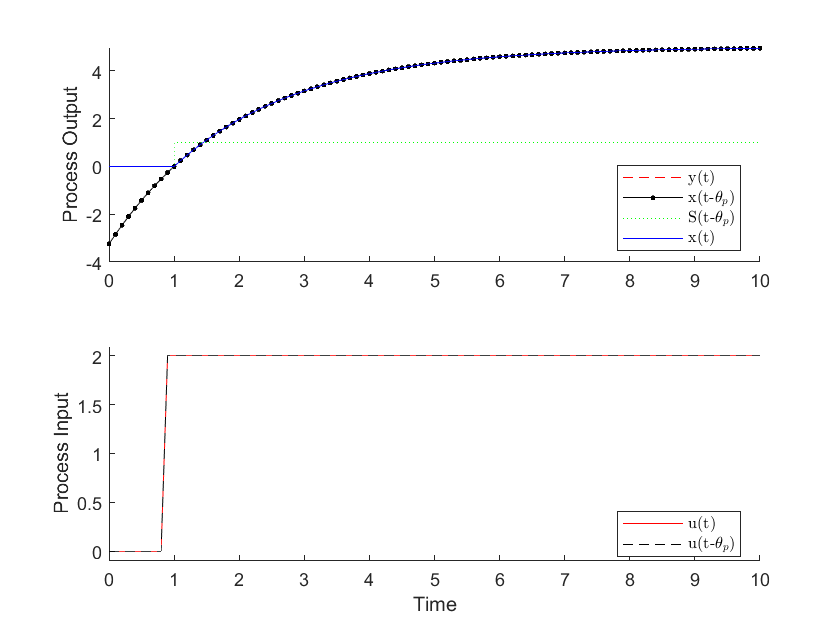

clf
figure(2)
% Specify number of steps
ns = 100;

%define time points
t = linspace(0, ns/10, ns +1);

% Calculate Step Response
Kp = 2.5;
taup = 2.0;
thetap = 0;

y = 1; %placeholder variable
[pv, op] = calc_response(t, y, Kp, taup, thetap);

pv2 = zeros(size(t));
for i = 1:length(t)
    pv2(i) = Kp*(1-exp(-(t(i)-thetap-1)/taup))*2;
end

pv3 = zeros(size(t));
for i = 1:length(t)
    pv3(i) = Kp*(1-exp(-(t(i)-1)/taup))*2;
end

subplot(2,1,1)
hold on
p1 = plot(t, pv3, 'r--');
p2 = plot(t, pv2, 'k.-');
p3 = plot([0,thetap+1,thetap+1.001,10],[0,0,1,1],'g:');
p4 = plot(t,pv,'b-');
ylim([-4,5])
ylabel('Process Output')
legend([p1, p2, p3, p4],{'y(t)','x(t-$\theta_p$)','S(t-$\theta_p$)', 'x(t)'}, 'Interpreter', "latex", 'Location',"best")

subplot(2,1,2)
hold on
p5 = plot(t,op, 'r-');
p6 = plot(t+thetap,op,'k--');
ylim([-0.1,2.1])
xlim([0,10])
ylabel('Process Input')
xlabel('Time')
legend([p5, p6], {'u(t)', 'u(t-$\theta_p$)'}, 'Interpreter', "latex", 'Location',"best")

# Graphical Method to Fit FOPDT Models Using a Step Test

Step test data are convenient for identifying an FOPDT model through a graphical fitting method. Follow the following steps when fitting the parameters $K_p$, $\tau_p$, $\theta_p$ to a step response.

- Find $\Delta y$ from step response

- Find $\Delta u
$ from step response

- Calculate $K_p = {\Delta y} / {\Delta u}$

- Find $\theta_p$, apparent dead time, from step response

- Find $0.632 \Delta y$ from step response

- Find $t_{0.632}$ for $y(t_{0.632}) = 0.632 \Delta y$ from step response

- Calculate $\tau_p = t_{0.632} - \theta_p$. This assumes that the step starts at t=0. If the step happens later, subtract the step time as well.

## Exercise

The model below is not a good fit of the process because the parameters have not been adjusted to match the data.

clf
figure(3)
Km = 0;
taum = 0;
thetam = 0;

Use the above steps to find parameters $K_p$, $\tau_p$, and $\theta_p$. Insert the updated parameters in the code and rerun the script to observe quality of the graphical fit in agreement with the simulated process data.

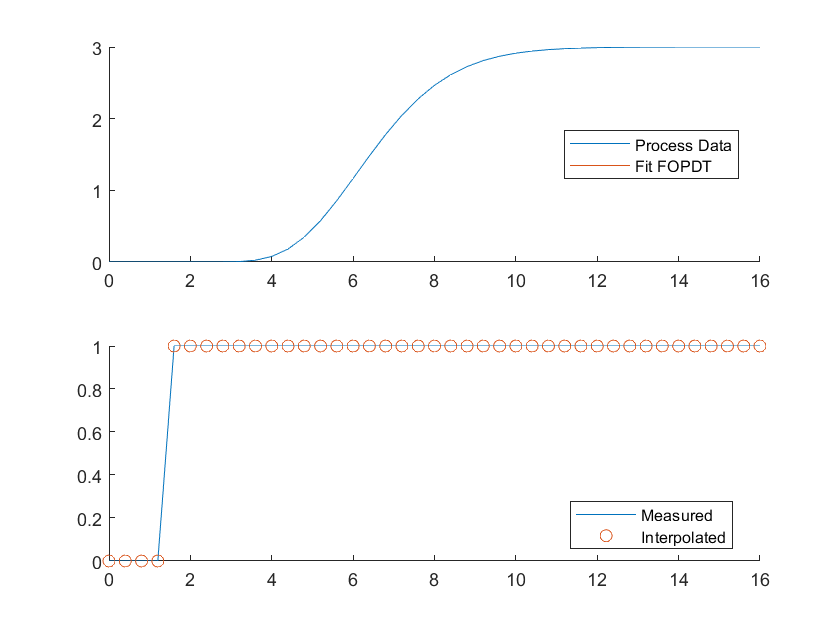

%specify number of points
ns = 40;
%define number of time points
t = linspace(0, 16, ns+1);
delta_t = t(2) - t(1);
tvals = t;
%define input vector
u = zeros(1, ns+1);
u(5:end) = 1;

yp = sim_process_data(u, delta_t, ns);

ym = sim_model(Km,taum,thetam, ns, delta_t, u, tvals);

subplot(2,1,1);
hold on
p2 = plot(t, yp);
p1 = plot(t, ym);
legend(["Process Data", "Fit FOPDT"], 'location', 'best')


subplot(2,1,2);
hold on
p3 = plot(t, u);
p4 = plot(t, interp1(t, u, t), 'o');
legend(["Measured", "Interpolated"], 'location', 'best')

function dydt = process_b(t,y,u,Kp,taup)
    % Kp = process gain
    % taup = process time constant
    dydt = -y/taup + Kp/taup * u;
end

function [pv, op] = calc_response(t, y, Kp, taup, thetap)
    % t = time points
    % m = process model
    % specify number of steps
    ns = length(t)-1;
    delta_t = t(2)-t(1);

    % storage for recording values
    op = zeros(1,ns+1);  % controller output
    pv = zeros(1,ns+1);  % process variable

    % step input
    op(10:end)= 2;

    % Simulate time delay
    ndelay = int64(ceil(thetap / delta_t));

    
    % loop through time steps    
    for i = 1:ns
        % implement time delay
        iop = max([1,i-ndelay-1]); 
        % define solutiont time span
        ts = [delta_t*(i-1),delta_t*i];
        % solve differential equation
        [t, y] = ode45(@(t,y) process_b(t, y, op(iop), Kp, taup), ts, pv(i));
        pv(i+1) = y(end);
        
    end
end

function dydt = process(t, y, n, u, Kp, taup)
    % arguments
    %  y[n] = outputs
    %  t    = time
    %  n    = order of the system  
    %  u    = input value
    %  Kp   = process gain
    %  taup = process time constant
    % equations for higher order system
    dydt = zeros(n,1);
    %size of y is determined by inital conditions
    % calculate derivative
    dydt(1,1) = (-y(1) + Kp * u)/(taup/n);
    for i = 2:n
       dydt(i,1) = (-y(i) + y(i-1))/(taup/n);
    end
end

% define first-order plus dead-time approximation    
function dydt = fopdt(t, y, u, tvals, Km,taum,thetam)
    % arguments
    %  y      = output
    %  t      = time
    %  uf     = input linear function (for time shift)
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model time constant
    % time-shift u
    try
        if (t-thetam) <= 0
            um = interp1(tvals, u, 0.0);%% IS A FUNCTION
        else
            um = interp1(tvals, u, t-thetam); %% IS A FUNCTION
        end
    catch 
        disp('Error with time extrapolation: ' + t )
        um = 0;
    end
    % calculate derivative
    dydt = (-y + Km * um)/taum;
end

% use this function or replace yp with real process data
function yp = sim_process_data(u, delta_t, ns)
    % higher order process
    n=10;       % order
    Kp=3.0;    % gain
    taup=5.0;   % time constant
    % storage for predictions or data
    yp = zeros(1,ns+1);  % process
    for i = 1:ns+1
        if i==1
            yp0 = zeros(1, n);
        end
        ts = [delta_t*(i-1),delta_t*i];
        [t, y] = ode45(@(t, y) process(t, y, n, u(i), Kp, taup), ts, yp0);  
        yp0 = y(end,:);
        yp(i) = y(2, n);
    end
end

% simulate FOPDT model with x=[Km,taum,thetam]
function ym = sim_model(Km,taum,thetam, ns, delta_t, u, tvals)
    % input arguments
    %Km
    %taum
    %thetam
    % storage for model values
    ym = zeros(1, (ns+1));  % model
    % initial condition
    ym(1) = 0;
    % loop through time steps    
    for i = 2:ns+1
        ts = [delta_t*(i-1),delta_t*i];
        [t, y1] = ode45(@(t, y) fopdt(t, y, u, tvals, Km,taum,thetam), ts, ym(i-1));
        ym(i) = y1(end);
    end
end

